## **Assignment1: Convolution and Difference Equation (DE)                 Kunanon Wanyen 66010103**

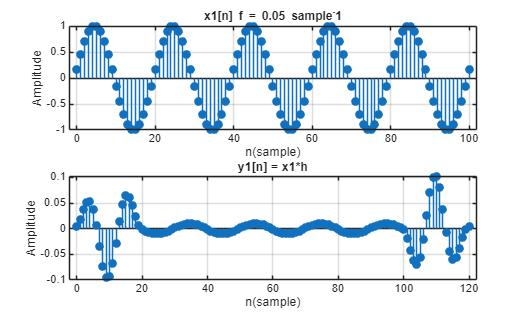

clear;
%FIR
n_x = 0:100;
fs1 = 0.05;
fs2 = 0.1;
fs3 = 0.2;

%xn = (sic,cos)(2*pi*fs*n + phase);
x1 = cos(2*pi*fs1*n_x + 30);
x2 = cos(2*pi*fs2*n_x + 60);
x3 = cos(2*pi*fs3*n_x + 90);


load("FIR.mat"); %<--call FIR.mat
n_h = 0:20;

n_y = 0:length(n_x) + length(n_h) - 2;

y1(1:length(n_y)) = 0;
y2(1:length(n_y)) = 0;
y3(1:length(n_y)) = 0;

for n = 0: length(n_y) - 1
    for k = 0: length(n_x) - 1

        if (n-k >= 0) && (n-k < length(n_h))
            y1(n+1) = y1(n+1) + x1(k+1)*hn(n-k+1);
            y2(n+1) = y2(n+1) + x2(k+1)*hn(n-k+1);
            y3(n+1) = y3(n+1) + x3(k+1)*hn(n-k+1);
        end

    end
end

figure(1);
set(gcf,'Name','FIR Response: x1[n] and y1[n] (f = 0.05)','NumberTitle','off');
subplot(2,1,1)
stem(n_x, x1, 'filled'); grid on;
title('x1[n] f = 0.05 sample^-1'); xlabel('n(sample)'); ylabel('Amplitude');
subplot(2,1,2);
stem(n_y, y1, 'filled'); grid on;
title('y1[n] = x1*h'); xlabel('n(sample)'); ylabel('Amplitude');

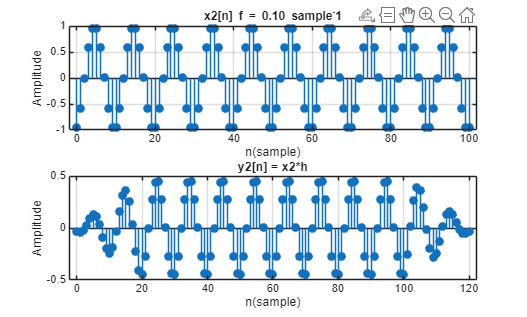


figure(2);
set(gcf,'Name','FIR Response: x2[n] and y2[n] (f = 0.10)','NumberTitle','off');
subplot(2,1,1)
stem(n_x, x2, 'filled'); grid on;
title('x2[n] f = 0.10 sample^-1'); xlabel('n(sample)'); ylabel('Amplitude');
subplot(2,1,2);
stem(n_y, y2, 'filled'); grid on;
title('y2[n] = x2*h'); xlabel('n(sample)'); ylabel('Amplitude');

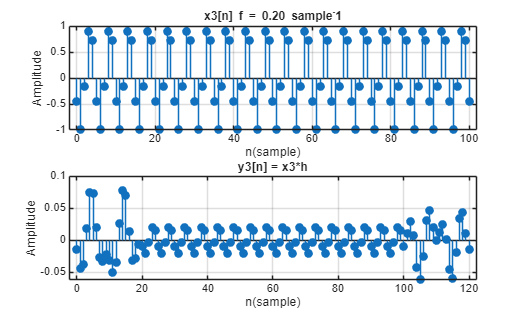


figure(3);
set(gcf,'Name','FIR Response: x3[n] and y3[n] (f = 0.20)','NumberTitle','off');
subplot(2,1,1)
stem(n_x, x3, 'filled'); grid on;
title('x3[n] f = 0.20 sample^-1'); xlabel('n(sample)'); ylabel('Amplitude');
subplot(2,1,2);
stem(n_y, y3, 'filled'); grid on;
title('y3[n] = x3*h'); xlabel('n(sample)'); ylabel('Amplitude');

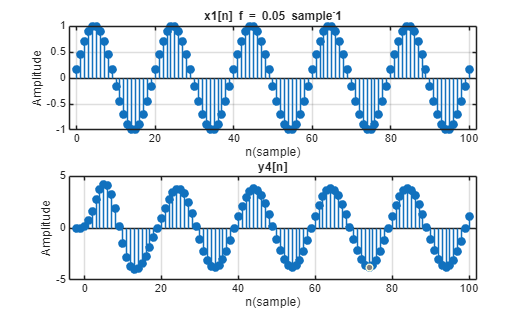


%IIR
% y[n] = 1.5y[n-1] - 0.85y[n-2] + x[n]
% n_de = -2 to 100 have 103 value start 0 : end 102
% n_de(0) = index -2
% n_de(1) = index -1
% n_de(3) = index 0

n_de = -2:100;

%define zero initial condition y[-2],y[-1] = 0
y4(1:length(n_de)) = 0;
y5(1:length(n_de)) = 0;
y6(1:length(n_de)) = 0;

for n = 0:100
    i = n + 3;
    y4(i) = 1.5*y4(i-1) - 0.85*y4(i-2) + x1(n+1);
    y5(i) = 1.5*y5(i-1) - 0.85*y5(i-2) + x2(n+1);
    y6(i) = 1.5*y6(i-1) - 0.85*y6(i-2) + x3(n+1);
end

figure(4);
set(gcf,'Name','IIR Response: x1[n] and y4[n] (f = 0.05)','NumberTitle','off');
subplot(2,1,1)
stem(n_x, x1, 'filled'); grid on;
title('x1[n] f = 0.05 sample^-1'); xlabel('n(sample)'); ylabel('Amplitude');
subplot(2,1,2);
stem(n_de, y4, 'filled'); grid on;
title('y4[n]'); xlabel('n(sample)'); ylabel('Amplitude');

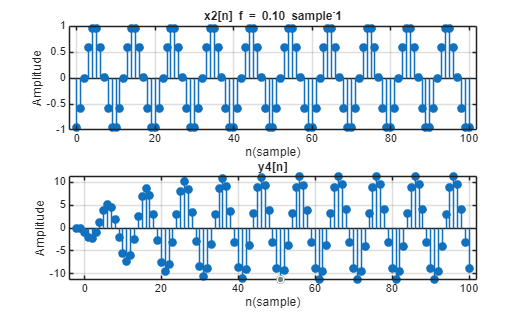


figure(5);
set(gcf,'Name','IIR Response: x2[n] and y5[n] (f = 0.10)','NumberTitle','off');
subplot(2,1,1)
stem(n_x, x2, 'filled'); grid on;
title('x2[n] f = 0.10 sample^-1'); xlabel('n(sample)'); ylabel('Amplitude');
subplot(2,1,2);
stem(n_de, y5, 'filled'); grid on;
title('y4[n]'); xlabel('n(sample)'); ylabel('Amplitude');

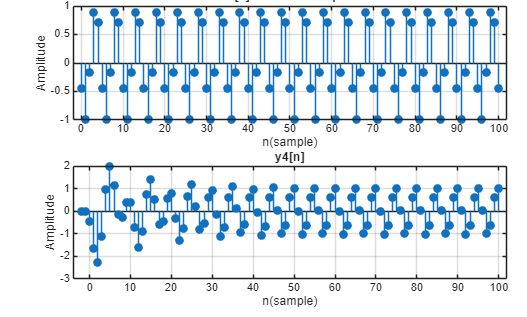


figure(6);
set(gcf,'Name','IIR Response: x3[n] and y6[n] (f = 0.20)','NumberTitle','off');
subplot(2,1,1)
stem(n_x, x3, 'filled'); grid on;
title('x3[n] f = 0.20 sample^-1'); xlabel('n(sample)'); ylabel('Amplitude');
subplot(2,1,2);
stem(n_de, y6, 'filled'); grid on;
title('y4[n]'); xlabel('n(sample)'); ylabel('Amplitude');